# The sine-Gordon equation on a tetrahedron graph

Solves the wave equation $u_{tt} - \triangle u + \sin{u} = 0$ on a tetrahedron graph, using the leapfrog method

### Set up the quantum graph

L = 10;
nX = 50;
G = solidTemplates('tetrahedron','nX',nX,'L',L);

#### Extending some definitions to the ghost points

The leapfrog method for a an ODE of the form $u''(t) = f(u)$, is a time stepping method of the form


$$u^{i+1} = u^{i} + (u^i-u^{i-1}) + \triangle t^2 f\left(u^i\right)$$


obtained by applying second-order centered difference stencil to the time derivative. 

L0 = G.laplacianMatrixWithZeros;
P0 = G.interpolationMatrixWithZeros;
PVC = G.interpolationMatrixWithVC;

#### Some time-stepping information

x =G.x{1}; dx = x(2)-x(1);
dt = dx/2;  % To obey the CFL condition
tfinal=30;
tprint = 1; % This should be an exact multiple of dt
nSteps=round(tfinal/dt);
nSkip=round(tprint/dt);
t=0:tprint:tfinal;
nt=length(t);

### Define the initial conditions

Recall that the leapfrog method requires the solution be given at times $t=0$ and $t=dt$. When the solution is a traveling wave, as here, we just use the (almost) exact solution at the two times.  If we are given the ordinary intial conditons of $u(x,0)= u_0(x)$ and $u_t(x,0)= v_0(x)$, then we may define the approximate solution at $t=dt$ using a second order Taylor approximation to be $u_1(x) = u_0(x) + v_0(x)\Delta t + \triangle u_0 \frac{\Delta t^2}{2}$. Instead, we simply take the moving soliton at times 0 and $dt$.

#### Define the solution at t = 0

c0 = 0.95;
f0 = @(x)4*atan(exp((x-L/2)/sqrt(1-c0^2)));
f1 = 2*pi;
G.applyFunctionsToAllEdges({f0,f0,f0,f1,f1,f1});
u0 =G.graph2column;

#### Define the solution at t = dt

f0 = @(x)4*atan(exp((x-L/2-c0*dt)/sqrt(1-c0^2)));
G.applyFunctionsToAllEdges({f0,f0,f0,f1,f1,f1});
u1 = G.graph2column;

### Evolve using the leapfrog method

U=zeros(length(u0),nt);
U(:,1)=u0; kt=1;
for k=2:nSteps
    u2 = PVC\(P0*(u1 + (u1-u0) - dt^2*sin(u1)) + dt^2*L0*u1);
    u0 = u1; u1 = u2;
    if mod(k,nSkip)==0
        kt=kt+1;
        U(:,kt)=u2;
    end
end

### Animate the solution

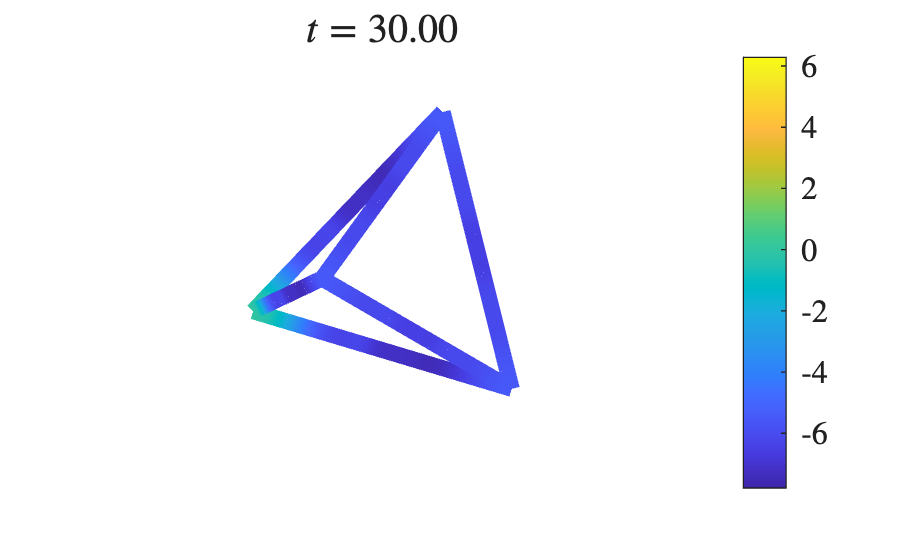

G.animatePDESolution(U,t)

uFinal=zeros(length(u2),3);
uFinal(:,1)=u2;
for j = 2:3
    dt = dt/2;
    nSteps=2*nSteps;
    f0 = @(x)4*atan(exp((x-L/2)/sqrt(1-c0^2)));
    f1 = 2*pi;
    G.applyFunctionsToAllEdges({f0,f0,f0,f1,f1,f1});
    u0 =G.graph2column;
    f0 = @(x)4*atan(exp((x-L/2-c0*dt)/sqrt(1-c0^2)));
    G.applyFunctionsToAllEdges({f0,f0,f0,f1,f1,f1});
    u1 = G.graph2column;
    for k=2:nSteps
        u2 = PVC\(P0*(u1 + (u1-u0) - dt^2*sin(u1)) + dt^2*L0*u1);
        u0 = u1; u1 = u2;
    end
    uFinal(:,j)=u2;
end

uDiff=diff(uFinal,1,2);
error1=G.norm(uDiff(:,1))

error1 = 0.0099

error2=G.norm(uDiff(:,2))

error2 = 0.0025

errorRatio= error1/error2

errorRatio = 3.9799